#### Setting the Seed 

rng(5)

#### The Value of  N is choosen from the List Below 

N_values = [5,10,20,40,60,80,100,500,1000,10000];
sz = length(N_values);

#### The parameters given in the Question

Mu_true = 10;
sig_true = 4;

#### The Matrices to store th Boxplots of each of the estimators

    ML_Mu_dev = zeros(100,sz);
    Mu_MAP1_dev = zeros(100,sz);
    Mu_MAP2_dev = zeros(100,sz);

#### Making the Draws for (M = 100) number of times 

for j=1:sz
    for i=1:100
         dataset = sig_true*randn(N_values(j),1)+ Mu_true*ones(N_values(j),1);
         ML_Mu = sum(dataset)/N_values(j);
         ML_Mu_dev(i,j) = abs(ML_Mu - Mu_true)/ Mu_true;

####                      CASE - I : PRIOR is G($\mu$, 10.5 ,1)

         Mu_MAP1 = ((16*10.5/(N_values(j)) + 1*ML_Mu))/(16/N_values(j) + 1);
         Mu_MAP1_dev(i,j) = abs(Mu_MAP1 - Mu_true)/ Mu_true;

####                      CASE- 2 : PRIOR is U(9.5, 11.5)

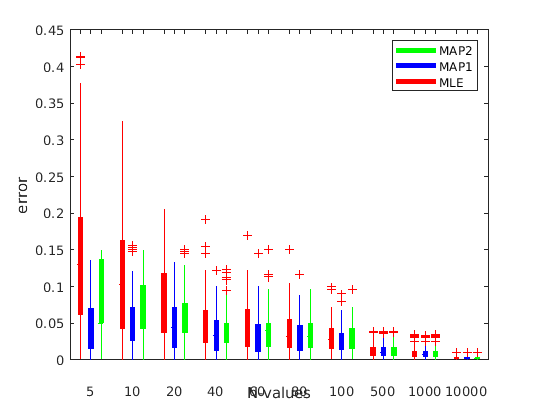

         if(ML_Mu > 11.5)
             Mu_MAP2 = 11.5;
         elseif (ML_Mu < 9.5) 
             Mu_MAP2 = 9.5;
         else
             Mu_MAP2 = ML_Mu;
         end
         Mu_MAP2_dev(i,j) = abs(Mu_MAP2  - Mu_true)/Mu_true;
    end
end
figure
labels = {' ',' ',' '};
grpLabels = {'5','10','20','40','60','80','100','500','1000','10000'};
x = {ML_Mu_dev,Mu_MAP1_dev, Mu_MAP2_dev};
boxplotGroup(x,'Colors', 'rbg','BoxStyle', 'filled','primaryLabels',labels,'SecondaryLabels',grpLabels)
xlabel("N-values");
ylabel("error") ;
ylim([0 0.45]);
h = findall(gca,'Tag','Box');
legend([h(1:1),h(11:11),h(21:21)],{'MAP2','MAP1','MLE'})